load supfigs_code/fit_stab_hilo_sim.mat

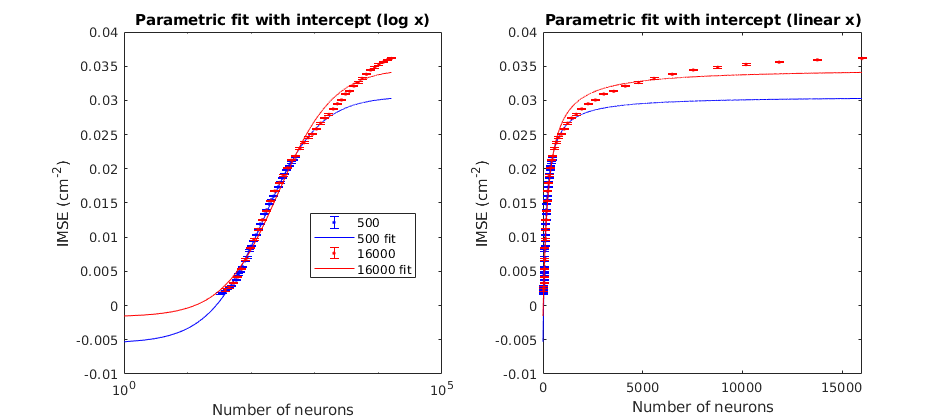

figure('Position', [ 1640         677         952         420])
subplot(1,2,1);
errorbar(n_low, mean(1./mse_low,1), sem(1./mse_low), '.b', 'DisplayName', '500');
hold on;
plot(1:max(n_high), fr_low(1:max(n_high)), 'b', 'DisplayName', '500 fit');
errorbar(n_high, mean(1./mse_high,1), sem(1./mse_high), '.r', 'DisplayName', '16000');
plot(1:max(n_high), fr_high(1:max(n_high)), 'r', 'DisplayName', '16000 fit');
set(gca, 'XScale', 'log');
title 'Parametric fit with intercept (log x)'
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'
legend Location best

subplot(1,2,2);
errorbar(n_low, mean(1./mse_low,1), sem(1./mse_low), '.b');
hold on;
plot(1:max(n_high), fr_low(1:max(n_high)), 'b');
errorbar(n_high, mean(1./mse_high,1), sem(1./mse_high), '.r');
plot(1:max(n_high), fr_high(1:max(n_high)), 'r');
set(gca, 'XScale', 'linear');
title 'Parametric fit with intercept (linear x)'
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'

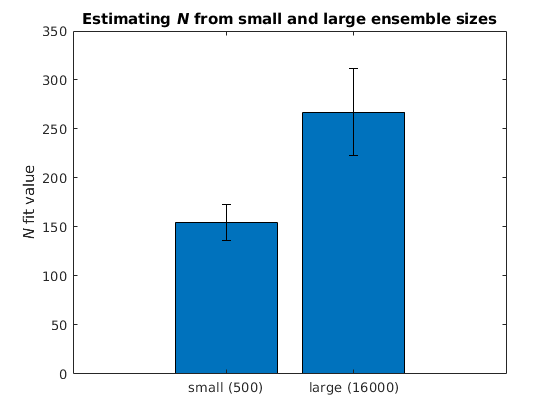

n_size_low = max(n_low);
n_size_high = max(n_high);
figure;
c = {sprintf('small (%d)', n_size_low), sprintf('large (%d)', n_size_high)};
N_vals = [fr_low.N fr_high.N];
N_conf = [get_ci(fr_low,'N') get_ci(fr_high, 'N')];
barerr([1 2], N_vals, N_conf);
ylabel '{\itN} fit value'
set(gca, 'XTickLabel', c);
title 'Estimating {\itN} from small and large ensemble sizes'

function ci = get_ci(fit_mdl, varname)
names = coeffnames(fit_mdl);
idx = find(strcmp(names, varname));
assert(numel(idx) == 1, 'Variable not found');

q = confint(fit_mdl);
q = q(:,idx);
ci = (q(2) - q(1))/2;
end